coinImage = imread("coinImage.png"); 

Let's have a look

[coinMask, maskedCoinImage] = segmentImageCoins(coinImage);

[maskedCoinImage,coinSizes] =  filterCoins(coinMask);

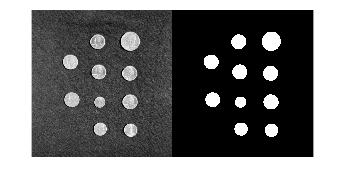

montage({coinImage,coinMask})

[coin_mask,coinSizes] =  filterCoins(BW)

coin_mask = 972×930 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

coinSizes = 10×2 table
    Area     Perimeter
    _____    _________

     7697     308.14  
     7675      307.9  
     7742     312.35  
     7688     308.26  
     6009      272.5  
     4184     226.24  
    12705     397.02  
     7707     308.14  
     7770     310.15  
     6076      274.1  


coinSizes = sortrows(coinSizes, "Area")

coinSizes = 10×2 table
    Area     Perimeter
    _____    _________

     4184     226.24  
     6009      272.5  
     6076      274.1  
     7675      307.9  
     7688     308.26  
     7697     308.14  
     7707     308.14  
     7742     312.35  
     7770     310.15  
    12705     397.02  


Now let's count how much money do we have

nDimes = sum(coinSizes.Perimeter < 260)

nDimes = 1

nNickels = sum((coinSizes.Perimeter > 270) & (coinSizes.Perimeter < 300) ) 

nNickels = 2

nQuarters = sum((coinSizes.Perimeter > 300) & (coinSizes.Perimeter < 320) )

nQuarters = 6

nFiftyCents = sum(coinSizes.Perimeter >350)

nFiftyCents = 1

USD = nDimes * 0.1 + nNickels * 0.05 + nQuarters * 0.25 + nFiftyCents * 0.5

USD = 2.2000